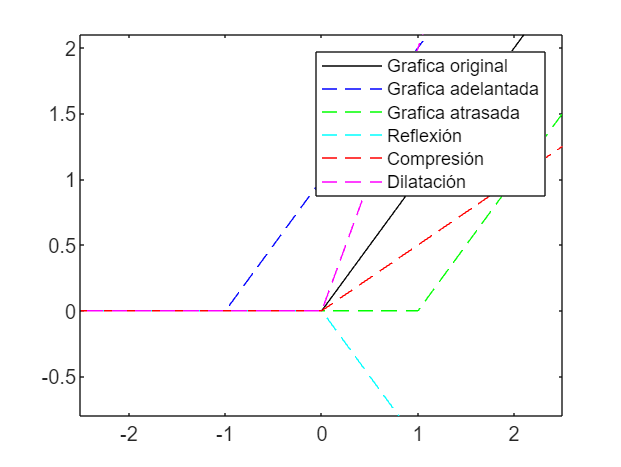

% Crear un vector de tiempo
t = -10:0.01:10;

ramp = zeros(size(t)); 

u_t = zeros(size(t));

for i = 1:length(t)
    if t(i) >= 0
        u_t(i) = 1; % u(t) es igual a 1 cuando t es mayor o igual a 0
    else
        u_t(i) = 0; % u(t) es igual a 0 cuando t es menor que 0
    end
end

% función rampa unida: t*u(t)
ramp = t .* u_t;

% Graficas 
figure;
title('Función Delta de Dirac');
xlabel('Tiempo');
ylabel('\delta(t)');

% Graficar la función delta(t) original
plot(t, ramp, "k", 'DisplayName', 'Grafica original');
axis([-2.5 2.5 -0.8 2.1]);
hold on

% Graficar la función delta(t) adelantada
plot(t-1, ramp, "--b", 'DisplayName', 'Grafica adelantada');

% Graficar la función delta(t) atrasada
plot(t+1, ramp, "--g", 'DisplayName', 'Grafica atrasada');

% Graficar la función delta(t) reflejada
plot(t, -ramp, "--c", 'DisplayName', 'Reflexión');

% Graficar la función delta(t) comprimida
plot(t*2, ramp, "--r", 'DisplayName', 'Compresión');

% Graficar la función delta(t) dilatada
plot(t/2, ramp, "--m", 'DisplayName', 'Dilatación');

legend;